load("test_functions2.mat","-mat")

f = f2;
gradf = gradf2;
Hessf = Hessf2;

c1 = 1e-4;
rho = 0.8;
btmax = 50;
em = eps();
h = 10*sqrt(em);
disp_int = [-100 100];
x_start = [-10 -5]';
[xk,fk,gradfk_norm,k,xseq,btseq] = newton_general(x_start,f,gradf,Hessf,kmax,tolgrad,c1,rho,btmax,true,"FW","FW",h)

xk =     1.0000
    1.0000


fk = 6.9037e-11

gradfk_norm = 7.1982e-05

k = 1000

xseq =   -10.0000   -9.9993   -9.4191   -9.2695   -8.7815   -8.5967   -8.0596   -7.9162   -7.4546   -7.2764   -6.7755   -6.6347   -6.2164   -6.0339   -5.6139   -5.4499   -4.9920   -4.8624   -4.4859   -4.3157   -3.9501   -3.7909   -3.4213   -3.2798   -2.8814   -2.7707   -2.3716   -2.2741   -1.9436   -1.8227   -1.4782   -1.3840   -1.0562   -0.9692   -0.6657   -0.5838   -0.3163   -0.2345    0.0325    0.0936    0.3086    0.3739    0.5531    0.6110    0.7693    0.8072    0.9403    0.9539    1.0057    1.0016
   -5.0000   99.9856   88.3835   85.9021   76.8624   73.8684   64.6530   62.6450   55.3440   52.9141   45.6413   43.9991   38.4550   36.3747   31.3239   29.6741   24.6976   23.6259   19.9700   18.5963   15.4553   14.3458   11.5567   10.7373    8.1340    7.6644    5.4583    5.1619    3.6623    3.3078    2.0592    1.9066    1.0030    0.9317    0.3468    0.3342    0.0246    0.0483   -0.0734    0.0051    0.0469    0.1356    0.2718    0.3700    0.5657    0.6501    0.8662    0.9097    1.0089  

btseq =      0     9     0     5     0     3     0     5     0     3     0     5     0     3     0     3     0     5     0     3     0     3     0     3     0     4     0     5     0     3     0     4     0     4     0     4     0     3     0     4     0     3     0     2     0     1     0     0     0     0


## Contour plot

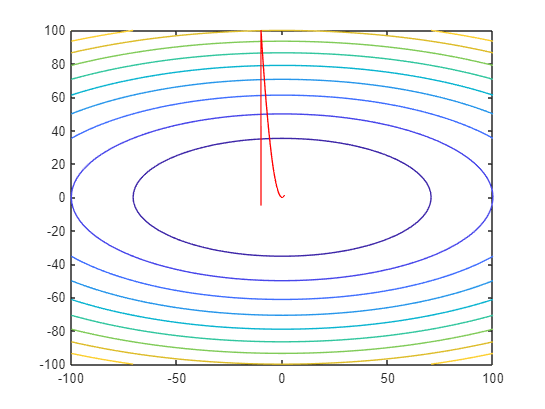

f1_meshgrid = @(X,Y)reshape(f1([X(:),Y(:)]'),size(X));
fcontour(f1_meshgrid,disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

## Surface plot

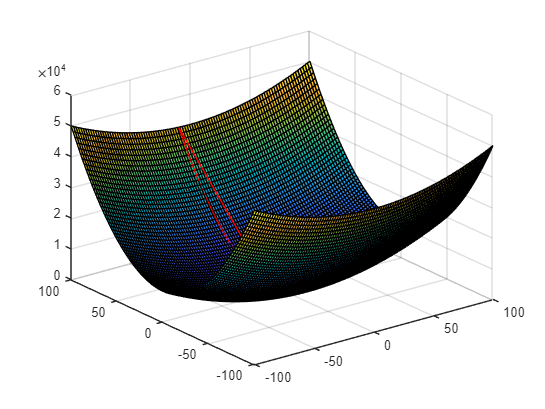

x = linspace(disp_int(1), disp_int(2));
[X,Y] = meshgrid(x,x);
f1_surf = f1_meshgrid(X,Y);

surf(X,Y,f1_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f1_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off

## Bar plot

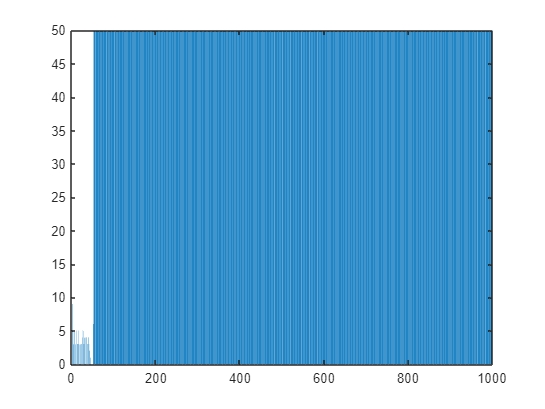

bar(btseq)